# Practice 1 

# BTC, Inflation and Stock portfolios

# Your name:

This version: 16/09/2024

## **Questions**

**Part 1 (2 Points)**

- Describe the basic characteristics of BTC excess monthly returns. Are they similar to standard financial assets (e.g., Stock Indexes)?. 

- Is the BTC a hedge against USA inflation during 2014-2024?. Present numerical evidence supporting your response. What are the implications of your results for BTC investing?

# Write your answer here

1.

2.

**Part 2** **(2 Points)**

- Request data for a number of symbols and calculate portfolios. Describe the main results in the efficient frontier. Compare optimal portfolios in the efficient frontier if (i) you can only take long positions (ii) you can take long and short positions. (iii) you restrict the portfolio to contain between 2 and 5 assets. Discuss the differences in results between (i), (ii) and (iii). Create an equally-weighted portfolio. Describe the main results. Is this portfolio in the efficient frontier?

- Cryptocurrency supporters argue that Bitcoin is a good asset diversifier of stock market risk. Does the data support this assertion?.

# Write your answer here

1.

2.

Email to ypenya@eco.uc3m.es your response in MLX and PDF files 

(Hint: Save a PDF version of your *.mlx file)

# Do not write in this section

## Part 1

clear all 
% import data on BTC and US Inflation
%   
clear all
% Get Risk-free 3-month interest rates
% Getting data from FRED
url = 'https://fred.stlouisfed.org/';
c = fred(url);
format bank
%  3-Month Treasury Bill Secondary Market Rate, Discount Basis (TB3MS)
% Monthly data. Yields in percent per annum (5.1 means 5.1% yearly)
series = 'TB3MS'; 
startdate = '11/01/2014'; % beginning of date range for historical data
enddate = '07/01/2024'; % ending of date range for historical data
d3m = fetch(c,series,startdate,enddate)

d3m = struct with fields:
                  NOTE: ' THIS DATA FILE WILL CHANGE! To improve accessibility of data for all users, we will convert this file from a text format to an html table by the end of June 2024.Title: 3-Month Treasury Bill Secondary Market Rate, Discount Basis'
              SeriesID: ' TB3MS'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1934-01-01 to 2024-08-01'
           LastUpdated: ' 2024-09-03 3:17 PM CDT'
                 Notes: ' Averages of Business Days, Discount Basis'
                  Data: [117×2 double]


dts3m = timeseries([d3m.Data(:,2)], datestr(d3m.Data(:,1)));
dts3m.Name = series;
plot(dts3m);
legend('3-Month Treasury Bill Secondary Market Rate, Discount Basis (TB3MS)',Location='best')
% Monthly-equivalent TB3MS
tb3mm=((d3m.Data(:,2))/100)/12;
disp('Request historical YTD Bitcoin price');

Request historical YTD Bitcoin price


%   INPUT:
    % symbol    - is a ticker symbol i.e. '^GSPC' corresponds to S&P500 Index
    % startdate - the date from which the market data will be requested
    % i.e. '1-Jan-1980'
    % enddate   - the market data will be requested till this date i.e.
    % '30-Feb-2020' (or datetime('today'))
    % interval  - the market data will be returned in this intervals
    % supported intervals are '1d', '5d', '1wk', '1mo', '3mo'
    %
	% OUTPUT:
    % data - is a retrieved  dataset returned as a table
    %
    % Example: 
    %   data = getMarketDataViaYahoo('AMD', '1-Jan-2018', datetime('today'), '1d');
initDate = '1-Oct-2014';
endDate='1-Jul-2024';
symbol = 'BTC-USD';
btcusd = readtable('/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/BTC.xlsx')

btcusd = 118×7 table
       Date          Open        Max         Min        Close      CloseAdj         Volume     
    ___________    ________    ________    ________    ________    ________    ________________

    01-Jul-2024    62673.61    69987.54    53717.38    64619.25    64619.25     953395573307.00
    01-Jun-2024    67489.61    71907.85    58601.70    62678.29    62678.29     726773965644.00
    01-May-2024    60609.50    71946.46    56555.29    67491.41    67491.41     874291509757.00
    01-Apr-2024    71333.48    72715.36    59120.07    60636.86    60636.86    1016068331704.00
    01-Mar-2024    61168.06    73750.07    59323.91    71333.65    71333.65    1446417844950.00
    01-Feb-2024    42569.76    63913.13    41879.19    61198.38    6

btcusd(1:5,:)

ans = 5×7 table
       Date          Open        Max         Min        Close      CloseAdj         Volume     
    ___________    ________    ________    ________    ________    ________    ________________

    01-Jul-2024    62673.61    69987.54    53717.38    64619.25    64619.25     953395573307.00
    01-Jun-2024    67489.61    71907.85    58601.70    62678.29    62678.29     726773965644.00
    01-May-2024    60609.50    71946.46    56555.29    67491.41    67491.41     874291509757.00
    01-Apr-2024    71333.48    72715.36    59120.07    60636.86    60636.86    1016068331704.00
    01-Mar-2024    61168.06    73750.07    59323.91    71333.65    71333.65    1446417844950.00


TT=table2timetable(btcusd);
figure, plot(TT.Date, TT.Close)
title('BTC Monthly Price')
warning ('off')
BTC_price=TT.Close;

% Compute monthly excess returns using periodic method
BTC_Returns=price2ret(BTC_price,Method="periodic");
BTC_ER= BTC_Returns - tb3mm;
figure, plot(TT.Date(2:end),BTC_ER)

title('BTC Monthly Periodic Excess Returns')
legend('BTC-USD');

% Descriptive statistics
NameVar='BTC Monthly ER ';
[Table1] = DescriptiveTable(BTC_ER,NameVar)

Table1 = 1×8 table
                      Sample_Size    Mean     Max      Min     STD     Skewness    Kurtosis    JBPval
                      ___________    _____    ____    _____    ____    ________    ________    ______

    BTC Monthly ER      117.00       -0.03    0.61    -0.41    0.20      0.72        3.81       0.01 


format short

% Tail risk VaR simple returns
rxs=BTC_ER;
VaR05s = quantile(rxs,0.05);
VaR01s= quantile(rxs,0.01);
VaR95s = quantile(rxs,0.95);
VaR99s= quantile(rxs,0.99);
Extreme_Losss=min(rxs);
Extreme_Profits=max(rxs);
TTs=table(Extreme_Losss, VaR01s,VaR05s,VaR95s,VaR99s, Extreme_Profits);
vr={'Simple returns'}

vr = 1×1 cell array
    {'Simple returns'}


TTs.Properties.RowNames = vr

TTs = 1×6 table
                      Extreme_Losss     VaR01s      VaR05s     VaR95s     VaR99s     Extreme_Profits
                      _____________    ________    ________    _______    _______    _______________

    Simple returns       -0.4106       -0.39593    -0.31764    0.36701    0.58372        0.60649    



% Getting data from FRED
url = 'https://fred.stlouisfed.org/';
c = fred(url);
format bank
% Consumer Price Index: All Items for the United States (USACPIALLMINMEI)
% Monthly data
% format month/day/year
series = 'USACPIALLMINMEI'; 
%startdate = '10/01/2010'; % beginning of date range for historical data
%enddate = '04/01/2024'; % ending of date range for historical data
CPI = fetch(c,series,startdate,enddate)

CPI = struct with fields:
                  NOTE: ' THIS DATA FILE WILL CHANGE! To improve accessibility of data for all users, we will convert this file from a text format to an html table by the end of June 2024.Title: Consumer Price Indices (CPIs, HICPs), COICOP 1999: Consumer Price Index: Total for United States'
              SeriesID: ' USACPIALLMINMEI'
                Source: ' Organization for Economic Co-operation and Development'
               Release: ' Main Economic Indicators (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Index 2015=100'
             DateRange: ' 1955-01-01 to 2024-08-01'
           LastUpdated: ' 2024-09-16 1:54 PM CDT'
                 Notes: ' OECD Data Filters:  REF_AREA: USA MEASURE: CPI UNIT_MEASURE: IX METHODOLOGY: N EXPENDITURE: _T ADJUSTMENT: N TRANSFORMATION: _Z FREQ: M  All OECD data should be cited as follows: OECD (year), (dataset name), (data source) DOI 

CPIm = timeseries([CPI.Data(:,2)], datestr(CPI.Data(:,1)));
CPIm.Name = series;
plot(CPIm)
CPI_USA=CPI.Data(:,2);
% Computing monthly inflation rate
InflationRate=price2ret(CPI_USA,Method="periodic");

CPIRm = timeseries([InflationRate], datestr(CPI.Data(2:end,1)));
CPIRm.Name = 'InflationRate';
plot(CPIRm)

% Create timetables
% Create timetables
BTCm = timeseries([BTC_ER], datestr(TT.Date(2:end)));

BTCm.Name = 'BTCEXReturns';
BTCX = timeseries2timetable(BTCm)

BTCX = 117×1 timetable
       Time        BTCEXReturns
    ___________    ____________

    01-Oct-2014       -0.11    
    01-Nov-2014        0.18    
    01-Dec-2014        0.47    
    01-Jan-2015       -0.15    
    01-Feb-2015        0.04    
    01-Mar-2015        0.03    
    01-Apr-2015        0.02    
    01-May-2015       -0.13    
    01-Jun-2015       -0.08    
    01-Jul-2015        0.23    
    01-Aug-2015       -0.03    
    01-Sep-2015       -0.25    
    01-Oct-2015       -0.17    
    01-Nov-2015       -0.13    
    01-Dec-2015        0.16    
    01-Jan-2016       -0.16    


CPIX = timeseries2timetable(CPIRm)

CPIX = 116×1 timetable
       Time        InflationRate
    ___________    _____________

    01-Dec-2014        -0.01    
    01-Jan-2015        -0.00    
    01-Feb-2015         0.00    
    01-Mar-2015         0.01    
    01-Apr-2015         0.00    
    01-May-2015         0.01    
    01-Jun-2015         0.00    
    01-Jul-2015         0.00    
    01-Aug-2015        -0.00    
    01-Sep-2015        -0.00    
    01-Oct-2015        -0.00    
    01-Nov-2015        -0.00    
    01-Dec-2015        -0.00    
    01-Jan-2016         0.00    
    01-Feb-2016         0.00    
    01-Mar-2016         0.00    


% Synchronize both series in a common sample


% Synchronize both series in a common sample

TTS=synchronize(BTCX,CPIX,'intersection')

TTS = 115×2 timetable
       Time        BTCEXReturns    InflationRate
    ___________    ____________    _____________

    01-Dec-2014        0.47            -0.01    
    01-Jan-2015       -0.15            -0.00    
    01-Feb-2015        0.04             0.00    
    01-Mar-2015        0.03             0.01    
    01-Apr-2015        0.02             0.00    
    01-May-2015       -0.13             0.01    
    01-Jun-2015       -0.08             0.00    
    01-Jul-2015        0.23             0.00    
    01-Aug-2015       -0.03            -0.00    
    01-Sep-2015       -0.25            -0.00    
    01-Oct-2015       -0.17            -0.00    
    01-Nov-2015       -0.13       

% Fill missing data with optimal interpolation
% See other vailable methods is command "fillmissing"
TTS=fillmissing(TTS,'pchip')

TTS = 115×2 timetable
       Time        BTCEXReturns    InflationRate
    ___________    ____________    _____________

    01-Dec-2014        0.47            -0.01    
    01-Jan-2015       -0.15            -0.00    
    01-Feb-2015        0.04             0.00    
    01-Mar-2015        0.03             0.01    
    01-Apr-2015        0.02             0.00    
    01-May-2015       -0.13             0.01    
    01-Jun-2015       -0.08             0.00    
    01-Jul-2015        0.23             0.00    
    01-Aug-2015       -0.03            -0.00    
    01-Sep-2015       -0.25            -0.00    
    01-Oct-2015       -0.17            -0.00    
    01-Nov-2015       -0.13       

scatter(TTS.InflationRate,TTS.BTCEXReturns)
title('BTC Monthly Returns (y) vs U.S. Inflation rate 2014-2024 (x)')
ylabel('BTC')
xlabel('InflationRate')

% Study relationship  between BTC ER and inflation rate

% Close FRED 

close(c)

## Part 2

disp('Request data for a number of symbols and calculate covariance matrix');

Request data for a number of symbols and calculate covariance matrix


% '^GSPC'=S&P500 Index, 
% '^N225'= NIKKEI225, 'GLD'=SPDR Gold Shares (GLD)
% 'QQQ'=Invesco QQQ Trust (QQQ), '^IXIC'=NASDAQ Composite (^IXIC),
% 'FNCL'=Fidelity MSCI Financials Index ETF (FNCL), ^IBEX = IBEX35 Index
clear marketData;
initDate = '1-Oct-2014';
endDate='1-Jul-2024';

symbols = {'^GSPC', '^N225', 'GLD', 'QQQ', '^IXIC', 'FNCL','^IBEX','BTC-USD'};
archivos = {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/SP500.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/Nikkei225.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/GoldShares.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/INVESCOQQQ.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/NASDAQ.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/Fidelity.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/IBEX35.xlsx','/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/BTC.xlsx'}

archivos = 1×8 cell array
    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/SP500.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/Nikkei225.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/GoldShares.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/INVESCOQQQ.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/NASDAQ.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/Fidelity.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/IBEX35.xlsx'}    {'/Users/edoardoanfelli/Desktop/UC3M/AV&S/AV&S.PRACTICE/Practice1_2024/BTC.xlsx'}


warning('off')
for k = 1:length(symbols)
    data = readtable(archivos{k});
    ts(k) = timeseries(data.Close, datestr(data(:,1).Date));
    tsout = resample(ts(k),ts(1).Time);  % Set a common sample size and dates to all series
    marketData(:,k) = tsout.Data;
end

marketData(isnan(marketData)) = 0; % In case resample() introduced NaNs
normalizedPrice = (marketData - mean(marketData))./std(marketData);
normalizedPrice = normalizedPrice - normalizedPrice(1,:);
tscomb = timeseries(normalizedPrice);

tscomb.TimeInfo = ts(1).TimeInfo;
tscomb.Name = 'normalized';
figure, plot(tscomb);
legend(symbols, 'interpreter', 'none', 'Location', 'best');
sp500=marketData(:,1);
OtherIndex=marketData(:,2:end);
covMat = corrcoef(marketData);
covMat(eye(length(symbols)) == 1) = 0;  

figure('Visible','on'),heatmap(covMat,'Colormap', parula(3), 'ColorbarVisible', 'on');
ax = gca;
ax.XData = symbols;
ax.YData = symbols;
title('Correlations Monthly Prices')

% Compute returns  
Returns=price2ret(marketData,Method="periodic");
Rsp500=Returns(:,1);
ROtherIndex=Returns(:,2:end);
figure, plot(Returns)
title('Monthly Periodic Returns')
legend(symbols, 'interpreter', 'none', 'Location', 'best');
covMat = corrcoef(Returns);
covMat(eye(length(symbols)) == 1) = 0;

figure, heatmap(covMat,'Colormap', parula(3), 'ColorbarVisible', 'on');
ax = gca;
ax.XData = symbols;
ax.YData = symbols;
title('Correlations Daily Returns')

format short
% Stock returns Portfolio
m = mean(Returns)
C = cov(Returns)
p = Portfolio('AssetList',symbols)
p = Portfolio(p, 'assetmean', m, 'assetcovar', C);

% Restrictions
p = Portfolio(p, 'lowerbudget', 1, 'upperbudget', 1);
p = Portfolio(p, 'lowerbound', 0);
 
plotFrontier(p);
pwgt = estimateFrontier(p, 5);
pnames = cell(1,5);
for i = 1:5
	pnames{i} = sprintf('Port%d',i);
end

Summary = dataset([{pwgt},pnames],'obsnames',p.AssetList);

% Optimal porftolios
disp(Summary);

% Optimal portfolios moments
[stdF, retF] = estimatePortMoments(p, pwgt)

% mean and std
hold on
plot(stdF,retF,'*r');
hold off 

% Set minimum and maximum assets 
% p = setMinMaxNumAssets(p,2,5)

%To create an equally weighted portfolio of four assets, use setTrackingPort:
p = setTrackingPort(p, 1/p.NumAssets, p.NumAssets);
disp(p.TrackingPort)
% Portfolio moments
[stdF_E, retF_E] = estimatePortMoments(p, p.TrackingPort)  % mean and std
plotFrontier(p)
hold on
plot(stdF_E,retF_E,'*r');
hold off 

## Local Functions

function [Table1] = DescriptiveTable(DatoX,NameVar)
    % Compute Table with Descriptive Statistics
    % 
Dyt=DatoX;
[h,lbqpal]=jbtest(Dyt);
TT=size(Dyt);
Table1=table(TT(1,1),mean(Dyt), max(Dyt),min(Dyt), std(Dyt),skewness(Dyt), kurtosis(Dyt), lbqpal);
Table1.Properties.VariableNames = {'Sample_Size','Mean','Max','Min', 'STD', 'Skewness', 'Kurtosis','JBPval'};
vr={NameVar};
Table1.Properties.RowNames = vr;

end

# Generating portfolios (the right answer)

All this section has been made after the presentation (just to inform), and i tried to do the work requested 

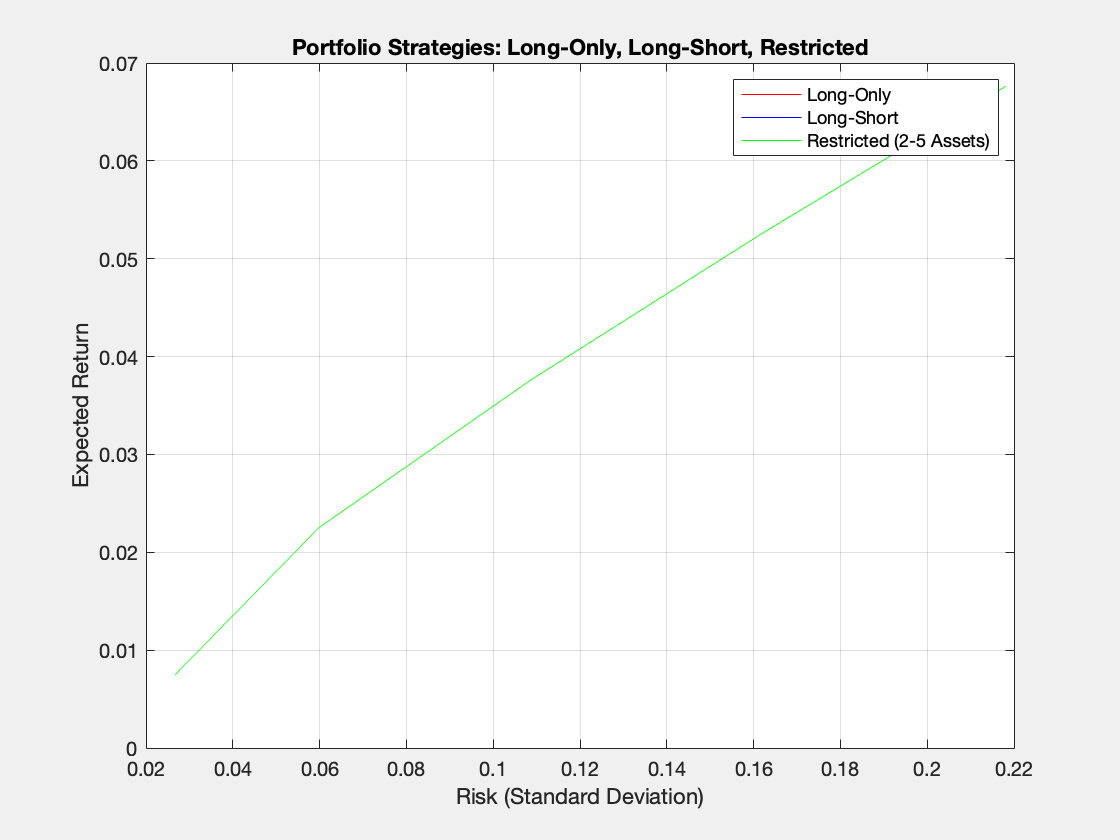

% Assuming 'Returns' is a 117x8 matrix of historical returns for the assets (117 observations)
% Calculate the mean returns across the time series for each asset
meanReturns = mean(Returns)';  % Transpose to make it a column vector (8x1)

% Covariance matrix (8x8) for the 8 assets
covMatrix = cov(Returns);  % Assuming Returns is 117x8 (117 observations of 8 assets)

% Extract the weights for each portfolio from your table
weights = [
    0       0       0       0       0;
    0.42437 0       0       0       0;
    0.5612  0.34459 0.011471 0       0;
    0       0.45601 0.55475 0.28396 0;
    0       0       0       0       0;
    0       0       0       0       0;
    0.014436 0      0       0       0;
    0       0.1994  0.43378 0.71604 1
];

% Define the number of portfolios
numPorts = size(weights, 2);

% Pre-allocate for results (long-only)
expectedReturns = zeros(1, numPorts);
risks = zeros(1, numPorts);

% Calculate expected returns and risks for each portfolio (long-only strategy)
for i = 1:numPorts
    w = weights(:, i);  % Get the weights for portfolio i
    expectedReturns(i) = w' * meanReturns;  % Calculate expected return
    risks(i) = sqrt(w' * covMatrix * w);  % Calculate portfolio risk (standard deviation)
end

% Plot for the long-only strategy
figure('Visible','on');
plot(risks, expectedReturns, 'r');
xlabel('Risk (Standard Deviation)');
ylabel('Expected Return');
title('Long-Only Strategy');
grid on;
hold on;

%% Long-Short Strategy
% Modify the weights to allow negative weights (you can choose how to do this)
% For simplicity, we'll assume the given weights already represent some possible long-short positions
% Here we just assume the original weights also work as a long-short strategy

weights_long_short = weights;  % Modify this if you want to manually assign negative weights

% Pre-allocate for long-short results
expectedReturns_long_short = zeros(1, numPorts);
risks_long_short = zeros(1, numPorts);

for i = 1:numPorts
    w = weights_long_short(:, i);  % Get the long-short weights for portfolio i
    expectedReturns_long_short(i) = w' * meanReturns;  % Calculate expected return
    risks_long_short(i) = sqrt(w' * covMatrix * w);  % Calculate portfolio risk (standard deviation)
end

% Add the long-short strategy to the plot
plot(risks_long_short, expectedReturns_long_short, 'b');

%% Restricted Strategy (2-5 assets)
% Restrict each portfolio to only the top 2-5 assets based on absolute weight

weights_restricted = zeros(size(weights));  % Pre-allocate restricted weights

for i = 1:numPorts
    [~, idx] = sort(abs(weights(:, i)), 'descend');  % Sort assets by absolute weight
    top_assets = idx(1:5);  % Select top 2-5 assets
    weights_restricted(top_assets, i) = weights(top_assets, i);  % Keep only top asset weights
end


% Pre-allocate for restricted strategy results
expectedReturns_restricted = zeros(1, numPorts);
risks_restricted = zeros(1, numPorts);

for i = 1:numPorts
    w = weights_restricted(:, i);  % Get the restricted weights for portfolio i
    expectedReturns_restricted(i) = w' * meanReturns;  % Calculate expected return
    risks_restricted(i) = sqrt(w' * covMatrix * w);  % Calculate portfolio risk (standard deviation)
end

% Add the restricted strategy to the plot
plot(risks_restricted, expectedReturns_restricted, 'g');

% Add legend and finish plotting
legend('Long-Only', 'Long-Short', 'Restricted (2-5 Assets)');
title('Portfolio Strategies: Long-Only, Long-Short, Restricted');
hold off;

# Generating portfolios (the wrong answer)

This is all the work i initially made to compute new portfolios, because i misunderstood the instrusctions, after the presentation i tried to do the right answer for question 1 part 2. I decided to keep it in the code so you, Professor, can take a look at it.

expectedReturns=[geomean(1+Returns)-1]' % Ensure expectedReturns is a column vector (8x1)

nAssets = 8;  % Number of assets

covMatrix = C  % Covariance matrix must be 8x8

% Create a Portfolio object
p = Portfolio;
p = p.setAssetMoments(expectedReturns, covMatrix);
p = p.setDefaultConstraints;  % Long-only by default

% 1. Efficient Frontier
stdF
retF

% 2. Create Specific Portfolios (Long-only, Long-Short, Equally Weighted, 2-5 Asset Portfolio)

% Long-only portfolio (default constraint)
weightsLongOnly = p.estimateMaxSharpeRatio;  % Get weights for maximum Sharpe ratio
riskLongOnly = sqrt(weightsLongOnly' * covMatrix * weightsLongOnly);  % Calculate risk (standard deviation)
returnLongOnly = weightsLongOnly' * expectedReturns;  % Calculate expected return (dot product of weights and returns)

% Long-short portfolio
pLS = p.setBounds(-1, 1);  % Allow long-short positions
weightsLongShort = pLS.estimateMaxSharpeRatio;
riskLongShort = sqrt(weightsLongShort' * covMatrix * weightsLongShort);
returnLongShort = weightsLongShort' * expectedReturns;

% Equally weighted portfolio
weightsEquallyWeighted = ones(nAssets, 1) / nAssets;
riskEquallyWeighted = sqrt(weightsEquallyWeighted' * covMatrix * weightsEquallyWeighted);
returnEquallyWeighted = weightsEquallyWeighted' * expectedReturns;

% Portfolio with 2 to 5 assets active
p25 = p.setMinMaxNumAssets(2, 5);  % Set the minimum of 2 assets and maximum of 5 assets
weights25Assets = p25.estimateMaxSharpeRatio;
risk25Assets = sqrt(weights25Assets' * covMatrix * weights25Assets);
return25Assets = weights25Assets' * expectedReturns;

% Plot the Efficient Frontier, here i copied the lines i found above in the code. 
figure('Visible','on');
plotFrontier(p);
pwgt = estimateFrontier(p, 5);
pnames = cell(1,5);
for i = 1:5
	pnames{i} = sprintf('Port%d',i);
end
hold on
% Plot the Long-Only Portfolio
plot(riskLongOnly, returnLongOnly, 'rs', 'MarkerSize', 7, 'MarkerFaceColor', 'r');  % Single point (red circle)

% Plot the Long-Short Portfolio
plot(riskLongShort, returnLongShort, 'bs', 'MarkerSize', 7, 'MarkerFaceColor', 'b');  % Single point (blue circle)

% Plot the Equally Weighted Portfolio
plot(riskEquallyWeighted, returnEquallyWeighted, 'gs', 'MarkerSize', 7, 'MarkerFaceColor', 'g');  % Single point (green circle)

% Plot the 2-5 Asset Portfolio
plot(risk25Assets, return25Assets, 'ms', 'MarkerSize', 7, 'MarkerFaceColor', 'm');  % Single point (magenta circle)

% Add labels and title
xlabel('Risk (Standard Deviation)');
ylabel('Expected Return');
title('Efficient Frontier with Different Portfolios');
legend('Efficient Frontier', 'Long-Only', 'Long-Short', 'Equally Weighted', '2-5 Assets');
grid on;
hold off;

% Now what we did was looking for stats of the 4 portfolios created to
% compare them
portfolioNames = {'Long-Only', 'Long-Short', 'Equally Weighted', '2-5 Assets'}';
ER = [returnLongOnly, returnLongShort, returnEquallyWeighted, return25Assets]';
risks = [riskLongOnly, riskLongShort, riskEquallyWeighted, risk25Assets]';

% add weights
weightsLongOnly = weightsLongOnly';  % Convert to rows
weightsLongShort = weightsLongShort';
weightsEquallyWeighted = weightsEquallyWeighted';
weights25Assets = weights25Assets';


Table1 = 1×8 table
                      Sample_Size     Mean     Max    Min     STD      Skewness    Kurtosis    JBPval 
                      ___________    ______    ___    ___    ______    ________    ________    _______

    BTC Monthly ER         1         77.167    95     66     11.686     0.4277      1.7314     0.48076


weightsMatrix = [weightsLongOnly; weightsLongShort; weightsEquallyWeighted; weights25Assets];


Table1 = 1×8 table
                 Sample_Size     Mean     Max    Min     STD      Skewness    Kurtosis     JBPval 
                 ___________    ______    ___    ___    ______    ________    ________    ________

    Inflation         1         102.15    116    73     12.707    -1.1012      3.3836     0.059336


% define asset names

Error using internal.stats.parseArgs (line 43)
Wrong number of arguments.

Error in corr (line 117)
[type,rows,tail,wts] = internal.stats.parseArgs(pnames,dflts,varargin{:});

assetNames = {'^GSPC', '^N225', 'GLD', 'QQQ', '^IXIC', 'FNCL', '^IBEX', 'BTC-USD'};

% create table
portfolioSummary = table(portfolioNames,ER, risks, ...
    weightsMatrix(:,1), weightsMatrix(:,2), weightsMatrix(:,3), weightsMatrix(:,4), ...
    weightsMatrix(:,5), weightsMatrix(:,6), weightsMatrix(:,7), weightsMatrix(:,8), ...
    'VariableNames', [{'Portfolio', 'ExpectedReturn', 'Risk'}, assetNames]);  

disp(portfolioSummary);

# BTC as an hedge

## Closer look at statistics of both, and their correlation 

NameVar='BTC Monthly ER ';
[Table1] = DescriptiveTable('BTC_ER',NameVar)
NameVar2='Inflation';
[Table1] = DescriptiveTable('InflationRate',NameVar2)
[R, P]=corr('BTC_Returns(1:116,1)', 'InflationRate')
%Since the p-value (0.8159) is much greater than your significance level, you would fail to reject the null hypothesis.
%This means the correlation of -0.02 is not statistically significant.
%Let's try to find regression
reg=fitlm(BTC_Returns(1:116),InflationRate)

# BTC as a diversifier

Closer look at correlation between BTC and Stocks (in this case SP500) to understand if BTC would act as diversifier.

[R, P] = corr(BTC_Returns,Rsp500) %find corr between btc and sp
%There is insufficient evidence to conclude that the observed correlation is statistically significant at the 1/117 significance level.
%The weak positive correlation of 0.1773 may have occurred by chance, and you cannot confidently state that there is a meaningful correlation between Bitcoin and the S&P 500 at this level of significance.
%We need more datas to compute it in a significant way
NameVar3='SP500 '; %describe sp
[Table1] = DescriptiveTable(Rsp500,NameVar3)